# Dialog: Search List

## Create the dialog

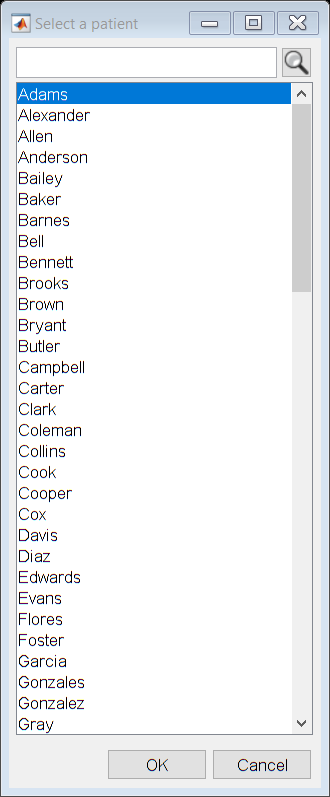

load('patients.mat','LastName');
LastName = sortrows(LastName);
d1 = uiw.dialog.SearchList(...
    'Title','Select a patient',...
    'DialogSize',[250 600],...
    'List',LastName);

## An alternate dialog, with initial selection made

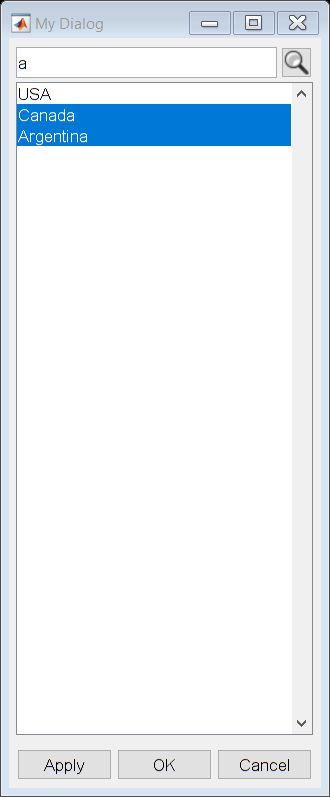

d2 = uiw.dialog.SearchList(...
    'Title','My Dialog',...
    'DialogSize',[250 600],...
    'Visible','on',...
    'List',{'USA','Canada','Mexico','Argentina'},...
    'SearchText','a',... %filters out Mexico
    'MultiSelect',true,...
    'ShowApply',true,...
    'SelectedIndex',[2 4]);

## Wait for output

% To wait for output and get a result:
%[out, action] = d.waitForOutput()